# Reto F3001C

Max Eduardo Garcia Esquivel - A01236070.

   %Code Variables
%Sizes
sXs = [1000,930,475,405];
sYs = [325,235,955,730];

%Paths
SuperiorPath = "./../Phase4V2/Sweeps/Matlab/";
FundamentalPath = "./../Phase3/Sweeps/Matlab/";

%Modes
Superior = "Waveguide%i_%i_532_Mode%i";
Fundamental = "Waveguide%i_%i_1596";
ModesSup = [15,9,19,12];

warning('off','MATLAB:polyfit:RepeatedPointsOrRescale')

## Waveguide selector:

sel = 1;
nmodes = ModesSup(sel);
mode = 15;
disp("Selected waveguide:")

Selected waveguide:


disp("   Size: "+num2str(sXs(sel))+"x"+num2str(sYs(sel)));

   Size: 1000x325


disp("   Mode: "+num2str(mode));

   Mode: 14


## Waveguide Summary:

disp("Waveguide: "+num2str(sXs(sel))+"x"+num2str(sXs(sel))+", mode: "+num2str(ModesSup(sel)));

Waveguide: 1000x1000, mode: 15


### Fundamental Mode Data (1596nm):

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
l = wgFundamental.lambdaData;
w = wgFundamental.omegaData;
neff = wgFundamental.neffData;

#### Ranges:

disp("Lambda Ranges: "+num2str(min(l))+"-"+num2str(max(l))+"");

Lambda Ranges: 1.53-1.596


disp("Omega Ranges: "+num2str(min(w))+"-"+num2str(max(w))+"");

Omega Ranges: 1181049869.7706-1231997119.0548


#### Neff vs ω/λ

disp("Function neff(λ):");

Function neff(λ):


disp(wgFundamental.nefflStr);

-0.000025750505326139147430292500*l.^30+0.000166135621290843785071572603*l.^29-0.000319608704624926799522238730*l.^28+0.000152668097566330322701830258*l.^27+0.000070621017376358761444450629*l.^26-0.001838478457877922586996555232*l.^25+0.006206450984080669891485015910*l.^24-0.001170051442921611140404736240*l.^23-0.009094709155628067157040028690*l.^22-0.005367800548884241705616116036*l.^21+0.017824193146289253608660629880*l.^20-0.032610375226340637677679978879*l.^19+0.045348849097638116445452283187*l.^18+0.097742963522884376836863395965*l.^17-0.128251133415534679382830063332*l.^16-0.060874472895750833534300738847*l.^15-0.089897454248084818217989777622*l.^14+0.060955126172131696149492086079*l.^13+0.979826240083205735054150409269*l.^12-3.135652427661680174963976241997*l.^11+2.342698772269560247849540246534*l.^10+4.218955241704159142557273298735*l.^9-5.893779769205091056960554851685*l.^8+10.325307005061949539026500133332*l.^7-28.457597161875764157912271912210*l.^6+27.05649732464337375859031

disp("Function neff(ω)");

Function neff(ω)


disp(wgFundamental.neffwStr);

1.257200516898534797702455388523e-271*w.^30-5.939522598070244281054868243553e-262*w.^29+8.172780059356416581688826103867e-253*w.^28-3.696834331080616900590136999288e-244*w.^27+8.395174076718721229700391628363e-235*w.^26-6.189097440278652978847385450896e-226*w.^25-2.722875438128554205896527150896e-216*w.^24+3.495345644823673478927616953786e-207*w.^23-2.373874583747627725979939167938e-198*w.^22+2.042246850655794837577147173729e-189*w.^21+1.537105644350316789498802518369e-180*w.^20+2.937502838082311446988486714118e-171*w.^19-9.078277301771214243512036546759e-162*w.^18+9.132537038207152846902646807185e-153*w.^17-1.617575934858211118517743363793e-143*w.^16+1.147298437203774206657335744237e-134*w.^15-1.901721548971641519133238186564e-125*w.^14+2.908993752078893954913370298545e-116*w.^13-2.462495261918159355220350787331e-107*w.^12+7.803745350803327321043926724508e-98*w.^11-1.308586632133808223402640807721e-89*w.^10-1.341238633500298104343060374577e-79*w.^9+5.092200101314285703914147246900e-71

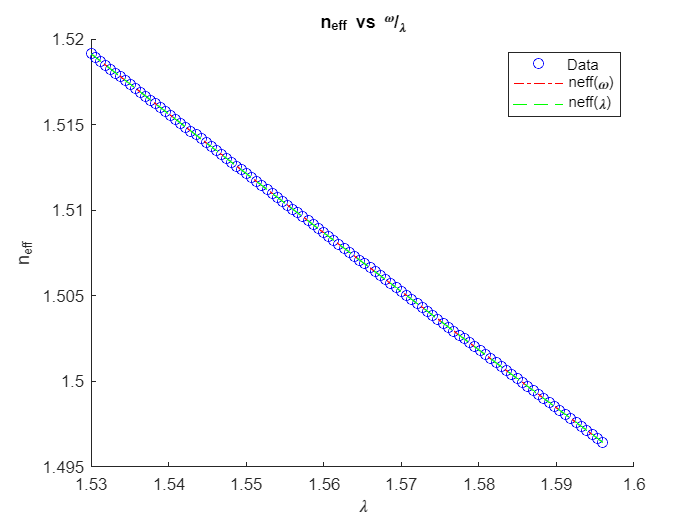

figure;
hold on
title("n_{eff} vs ^{\omega}/_{\lambda}");
plot(l,neff,'bo',l,wgFundamental.neffwFun(w),'r-.',l,wgFundamental.nefflFun(l),'g--');
legend(["Data","neff(\omega)","neff(\lambda)"]);
xlabel("\lambda");
ylabel("n_{eff}");
hold off

#### Subfunctions (k, dw, Vg, d2w, D)

disp("Function k(ω):");

Function k(ω):


disp(wgFundamental.kwStr);

w.*(1.257200516898534797702455388523e-271*w.^30-5.939522598070244281054868243553e-262*w.^29+8.172780059356416581688826103867e-253*w.^28-3.696834331080616900590136999288e-244*w.^27+8.395174076718721229700391628363e-235*w.^26-6.189097440278652978847385450896e-226*w.^25-2.722875438128554205896527150896e-216*w.^24+3.495345644823673478927616953786e-207*w.^23-2.373874583747627725979939167938e-198*w.^22+2.042246850655794837577147173729e-189*w.^21+1.537105644350316789498802518369e-180*w.^20+2.937502838082311446988486714118e-171*w.^19-9.078277301771214243512036546759e-162*w.^18+9.132537038207152846902646807185e-153*w.^17-1.617575934858211118517743363793e-143*w.^16+1.147298437203774206657335744237e-134*w.^15-1.901721548971641519133238186564e-125*w.^14+2.908993752078893954913370298545e-116*w.^13-2.462495261918159355220350787331e-107*w.^12+7.803745350803327321043926724508e-98*w.^11-1.308586632133808223402640807721e-89*w.^10-1.341238633500298104343060374577e-79*w.^9+5.092200101314285703914147246900

disp("Function dk(ω)/dω:");

Function dk(ω)/dω:


disp(wgFundamental.dkwdwStr);

(1.257200516898534797702455388523e-271*w.^30*(31)-5.939522598070244281054868243553e-262*w.^29*(30)+8.172780059356416581688826103867e-253*w.^28*(29)-3.696834331080616900590136999288e-244*w.^27*(28)+8.395174076718721229700391628363e-235*w.^26*(27)-6.189097440278652978847385450896e-226*w.^25*(26)-2.722875438128554205896527150896e-216*w.^24*(25)+3.495345644823673478927616953786e-207*w.^23*(24)-2.373874583747627725979939167938e-198*w.^22*(23)+2.042246850655794837577147173729e-189*w.^21*(22)+1.537105644350316789498802518369e-180*w.^20*(21)+2.937502838082311446988486714118e-171*w.^19*(20)-9.078277301771214243512036546759e-162*w.^18*(19)+9.132537038207152846902646807185e-153*w.^17*(18)-1.617575934858211118517743363793e-143*w.^16*(17)+1.147298437203774206657335744237e-134*w.^15*(16)-1.901721548971641519133238186564e-125*w.^14*(15)+2.908993752078893954913370298545e-116*w.^13*(14)-2.462495261918159355220350787331e-107*w.^12*(13)+7.803745350803327321043926724508e-98*w.^11*(12)-1.308586632133808223

disp("Function Vg(ω):");

Function Vg(ω):


disp(wgFundamental.vgwStr);

(3*10^8)./(1.257200516898534797702455388523e-271*w.^30*(31)-5.939522598070244281054868243553e-262*w.^29*(30)+8.172780059356416581688826103867e-253*w.^28*(29)-3.696834331080616900590136999288e-244*w.^27*(28)+8.395174076718721229700391628363e-235*w.^26*(27)-6.189097440278652978847385450896e-226*w.^25*(26)-2.722875438128554205896527150896e-216*w.^24*(25)+3.495345644823673478927616953786e-207*w.^23*(24)-2.373874583747627725979939167938e-198*w.^22*(23)+2.042246850655794837577147173729e-189*w.^21*(22)+1.537105644350316789498802518369e-180*w.^20*(21)+2.937502838082311446988486714118e-171*w.^19*(20)-9.078277301771214243512036546759e-162*w.^18*(19)+9.132537038207152846902646807185e-153*w.^17*(18)-1.617575934858211118517743363793e-143*w.^16*(17)+1.147298437203774206657335744237e-134*w.^15*(16)-1.901721548971641519133238186564e-125*w.^14*(15)+2.908993752078893954913370298545e-116*w.^13*(14)-2.462495261918159355220350787331e-107*w.^12*(13)+7.803745350803327321043926724508e-98*w.^11*(12)-1.30858663

disp("Function d2k(ω)/dω:");

Function d2k(ω)/dω:


disp(wgFundamental.d2kwdw2Str);

(1.257200516898534797702455388523e-271*w.^29*(930)-5.939522598070244281054868243553e-262*w.^28*(870)+8.172780059356416581688826103867e-253*w.^27*(812)-3.696834331080616900590136999288e-244*w.^26*(756)+8.395174076718721229700391628363e-235*w.^25*(702)-6.189097440278652978847385450896e-226*w.^24*(650)-2.722875438128554205896527150896e-216*w.^23*(600)+3.495345644823673478927616953786e-207*w.^22*(552)-2.373874583747627725979939167938e-198*w.^21*(506)+2.042246850655794837577147173729e-189*w.^20*(462)+1.537105644350316789498802518369e-180*w.^19*(420)+2.937502838082311446988486714118e-171*w.^18*(380)-9.078277301771214243512036546759e-162*w.^17*(342)+9.132537038207152846902646807185e-153*w.^16*(306)-1.617575934858211118517743363793e-143*w.^15*(272)+1.147298437203774206657335744237e-134*w.^14*(240)-1.901721548971641519133238186564e-125*w.^13*(210)+2.908993752078893954913370298545e-116*w.^12*(182)-2.462495261918159355220350787331e-107*w.^11*(156)+7.803745350803327321043926724508e-98*w.^10*(132)-

disp("Function D(ω):");

Function D(ω):


disp(wgFundamental.DwStr);

-(w.^2/(2*pi*3*10^8)).*((1.257200516898534797702455388523e-271*w.^29*(930)-5.939522598070244281054868243553e-262*w.^28*(870)+8.172780059356416581688826103867e-253*w.^27*(812)-3.696834331080616900590136999288e-244*w.^26*(756)+8.395174076718721229700391628363e-235*w.^25*(702)-6.189097440278652978847385450896e-226*w.^24*(650)-2.722875438128554205896527150896e-216*w.^23*(600)+3.495345644823673478927616953786e-207*w.^22*(552)-2.373874583747627725979939167938e-198*w.^21*(506)+2.042246850655794837577147173729e-189*w.^20*(462)+1.537105644350316789498802518369e-180*w.^19*(420)+2.937502838082311446988486714118e-171*w.^18*(380)-9.078277301771214243512036546759e-162*w.^17*(342)+9.132537038207152846902646807185e-153*w.^16*(306)-1.617575934858211118517743363793e-143*w.^15*(272)+1.147298437203774206657335744237e-134*w.^14*(240)-1.901721548971641519133238186564e-125*w.^13*(210)+2.908993752078893954913370298545e-116*w.^12*(182)-2.462495261918159355220350787331e-107*w.^11*(156)+7.80374535080332732104392

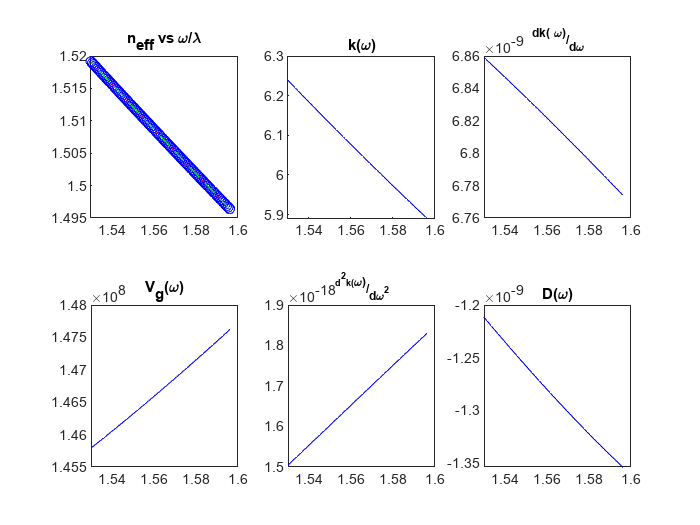

subplot(2,3,1);
plot(l,neff,'bo',l,wgFundamental.neffwFun(w),'r-.',l,wgFundamental.nefflFun(l),'g--');
title("n_{eff} vs \omega/\lambda");
subplot(2,3,2);
plot(l,wgFundamental.kwFun(w),'b');
title("k(\omega)");
subplot(2,3,3);
plot(l,wgFundamental.dkwdwFun(w),'b');
title("^{dk(\omega)}/_{d\omega}");
subplot(2,3,4);
plot(l,wgFundamental.vgwFun(w),'b');
title("V_g(\omega)");
subplot(2,3,5);
plot(l,wgFundamental.d2kwdw2Fun(w),'b');
title("^{d^2k(\omega)}/_{d\omega^2}");
subplot(2,3,6);
plot(l,wgFundamental.DwFun(w),'b');
title("D(\omega)");

### Superior Mode Data (530nm):

file = sprintf(Superior,sXs(sel),sYs(sel),ModesSup(sel));
load(SuperiorPath+file);
wgSuperior = waveguide(lambda,neff);
l = wgSuperior.lambdaData;
w = wgSuperior.omegaData;
neff = wgSuperior.neffData;

#### Ranges:

disp("Lambda Ranges: "+num2str(min(l))+"-"+num2str(max(l))+"");

Lambda Ranges: 0.51-0.532


disp("Omega Ranges: "+num2str(min(w))+"-"+num2str(max(w))+"");

Omega Ranges: 3543149609.3118-3695991357.1645


#### Neff vs ω/λ

disp("Function neff(λ):");

Function neff(λ):


disp(wgSuperior.nefflStr);

-170857623001945.437500000000000000000000000000*l.^30+544734642199373.437500000000000000000000000000*l.^29-665486652354275.000000000000000000000000000000*l.^28+402107547210824.000000000000000000000000000000*l.^27-111915602213414.171875000000000000000000000000*l.^26-48377414434317.171875000000000000000000000000*l.^25+72638252765697.421875000000000000000000000000*l.^24-9708830805750.363281250000000000000000000000*l.^23-17479586412023.691406250000000000000000000000*l.^22+2258128954518.872070312500000000000000000000*l.^21+1574229304230.769287109375000000000000000000*l.^20+1905245589853.415771484375000000000000000000*l.^19-1375221583476.281738281250000000000000000000*l.^18+442491553251.356933593750000000000000000000*l.^17-60852845589.279998779296875000000000000000*l.^16-75222760330.362411499023437500000000000000*l.^15+1321443806.616632699966430664062500000000*l.^14+16775607437.424379348754882812500000000000*l.^13-10583734065.733318328857421875000000000000*l.^12+11177400991.02490043640136718

disp("Function neff(ω):");

Function neff(ω):


disp(wgSuperior.neffwStr);

4.393310814495142809142406236547e-282*w.^30-2.360636067323359288727349250688e-272*w.^29-8.368209737761589600978293870279e-263*w.^28-3.434517398721498691798970512021e-254*w.^27+1.114062236264454991899228394168e-244*w.^26+2.850583239812543064348802126856e-233*w.^25+1.659114383938514234773080653518e-224*w.^24-4.138919780680062773841511275498e-214*w.^23-1.950022048457480133264224322529e-204*w.^22+4.127113370515063497829858001909e-195*w.^21+5.723941836089124181346834699476e-186*w.^20+6.108794328733134671065448771597e-176*w.^19+3.221195669422929924346228364704e-166*w.^18-8.166015815762064495877294430377e-157*w.^17-4.898021842903473902840429772766e-147*w.^16-3.594468159085281653331404046652e-138*w.^15+6.147471924736980699213150631219e-129*w.^14+9.287953051601334712111494747648e-119*w.^13+1.882955867062298538488846510338e-109*w.^12-3.175572314983938863361372788200e-100*w.^11+4.403567696998419627888981023518e-90*w.^10+1.932703706902148949622055233592e-81*w.^9-8.775218174797017547696178868135e-7

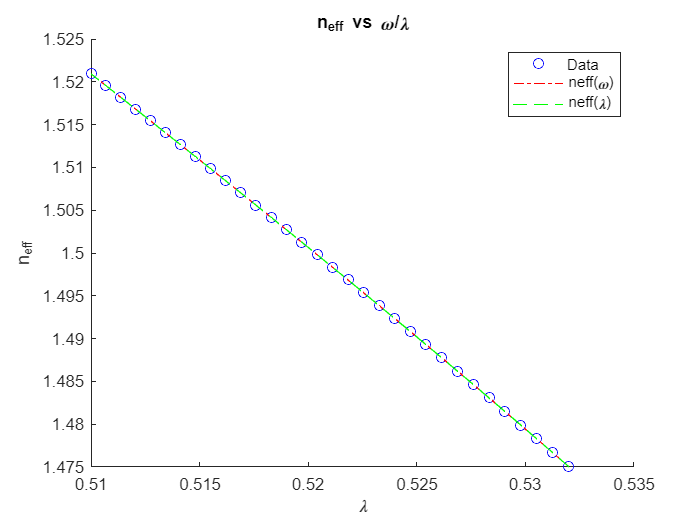

figure;
hold on
title("n_{eff} vs \omega/\lambda");
plot(l,neff,'bo',l,wgSuperior.neffwFun(w),'r-.',l,wgSuperior.nefflFun(l),'g--');
legend(["Data","neff(\omega)","neff(\lambda)"]);
xlabel("\lambda");
ylabel("n_{eff}");
hold off

#### Subfunctions (k, dw, Vg, d2w, D)

disp("Function k(ω):");

Function k(ω):


disp(wgSuperior.kwStr);

w.*(4.393310814495142809142406236547e-282*w.^30-2.360636067323359288727349250688e-272*w.^29-8.368209737761589600978293870279e-263*w.^28-3.434517398721498691798970512021e-254*w.^27+1.114062236264454991899228394168e-244*w.^26+2.850583239812543064348802126856e-233*w.^25+1.659114383938514234773080653518e-224*w.^24-4.138919780680062773841511275498e-214*w.^23-1.950022048457480133264224322529e-204*w.^22+4.127113370515063497829858001909e-195*w.^21+5.723941836089124181346834699476e-186*w.^20+6.108794328733134671065448771597e-176*w.^19+3.221195669422929924346228364704e-166*w.^18-8.166015815762064495877294430377e-157*w.^17-4.898021842903473902840429772766e-147*w.^16-3.594468159085281653331404046652e-138*w.^15+6.147471924736980699213150631219e-129*w.^14+9.287953051601334712111494747648e-119*w.^13+1.882955867062298538488846510338e-109*w.^12-3.175572314983938863361372788200e-100*w.^11+4.403567696998419627888981023518e-90*w.^10+1.932703706902148949622055233592e-81*w.^9-8.77521817479701754769617886813

disp("Function dk(ω)/dω:");

Function dk(ω)/dω:


disp(wgSuperior.dkwdwStr);

(4.393310814495142809142406236547e-282*w.^30*(31)-2.360636067323359288727349250688e-272*w.^29*(30)-8.368209737761589600978293870279e-263*w.^28*(29)-3.434517398721498691798970512021e-254*w.^27*(28)+1.114062236264454991899228394168e-244*w.^26*(27)+2.850583239812543064348802126856e-233*w.^25*(26)+1.659114383938514234773080653518e-224*w.^24*(25)-4.138919780680062773841511275498e-214*w.^23*(24)-1.950022048457480133264224322529e-204*w.^22*(23)+4.127113370515063497829858001909e-195*w.^21*(22)+5.723941836089124181346834699476e-186*w.^20*(21)+6.108794328733134671065448771597e-176*w.^19*(20)+3.221195669422929924346228364704e-166*w.^18*(19)-8.166015815762064495877294430377e-157*w.^17*(18)-4.898021842903473902840429772766e-147*w.^16*(17)-3.594468159085281653331404046652e-138*w.^15*(16)+6.147471924736980699213150631219e-129*w.^14*(15)+9.287953051601334712111494747648e-119*w.^13*(14)+1.882955867062298538488846510338e-109*w.^12*(13)-3.175572314983938863361372788200e-100*w.^11*(12)+4.40356769699841962

disp("Function Vg(ω):");

Function Vg(ω):


disp(wgSuperior.vgwStr);

(3*10^8)./(4.393310814495142809142406236547e-282*w.^30*(31)-2.360636067323359288727349250688e-272*w.^29*(30)-8.368209737761589600978293870279e-263*w.^28*(29)-3.434517398721498691798970512021e-254*w.^27*(28)+1.114062236264454991899228394168e-244*w.^26*(27)+2.850583239812543064348802126856e-233*w.^25*(26)+1.659114383938514234773080653518e-224*w.^24*(25)-4.138919780680062773841511275498e-214*w.^23*(24)-1.950022048457480133264224322529e-204*w.^22*(23)+4.127113370515063497829858001909e-195*w.^21*(22)+5.723941836089124181346834699476e-186*w.^20*(21)+6.108794328733134671065448771597e-176*w.^19*(20)+3.221195669422929924346228364704e-166*w.^18*(19)-8.166015815762064495877294430377e-157*w.^17*(18)-4.898021842903473902840429772766e-147*w.^16*(17)-3.594468159085281653331404046652e-138*w.^15*(16)+6.147471924736980699213150631219e-129*w.^14*(15)+9.287953051601334712111494747648e-119*w.^13*(14)+1.882955867062298538488846510338e-109*w.^12*(13)-3.175572314983938863361372788200e-100*w.^11*(12)+4.4035676

disp("Function d2k(ω)/dω2:");

Function d2k(ω)/dω2:


disp(wgSuperior.d2kwdw2Str);

(4.393310814495142809142406236547e-282*w.^29*(930)-2.360636067323359288727349250688e-272*w.^28*(870)-8.368209737761589600978293870279e-263*w.^27*(812)-3.434517398721498691798970512021e-254*w.^26*(756)+1.114062236264454991899228394168e-244*w.^25*(702)+2.850583239812543064348802126856e-233*w.^24*(650)+1.659114383938514234773080653518e-224*w.^23*(600)-4.138919780680062773841511275498e-214*w.^22*(552)-1.950022048457480133264224322529e-204*w.^21*(506)+4.127113370515063497829858001909e-195*w.^20*(462)+5.723941836089124181346834699476e-186*w.^19*(420)+6.108794328733134671065448771597e-176*w.^18*(380)+3.221195669422929924346228364704e-166*w.^17*(342)-8.166015815762064495877294430377e-157*w.^16*(306)-4.898021842903473902840429772766e-147*w.^15*(272)-3.594468159085281653331404046652e-138*w.^14*(240)+6.147471924736980699213150631219e-129*w.^13*(210)+9.287953051601334712111494747648e-119*w.^12*(182)+1.882955867062298538488846510338e-109*w.^11*(156)-3.175572314983938863361372788200e-100*w.^10*(132)

disp("Function D(ω):");

Function D(ω):


disp(wgSuperior.DwStr);

-(w.^2/(2*pi*3*10^8)).*((4.393310814495142809142406236547e-282*w.^29*(930)-2.360636067323359288727349250688e-272*w.^28*(870)-8.368209737761589600978293870279e-263*w.^27*(812)-3.434517398721498691798970512021e-254*w.^26*(756)+1.114062236264454991899228394168e-244*w.^25*(702)+2.850583239812543064348802126856e-233*w.^24*(650)+1.659114383938514234773080653518e-224*w.^23*(600)-4.138919780680062773841511275498e-214*w.^22*(552)-1.950022048457480133264224322529e-204*w.^21*(506)+4.127113370515063497829858001909e-195*w.^20*(462)+5.723941836089124181346834699476e-186*w.^19*(420)+6.108794328733134671065448771597e-176*w.^18*(380)+3.221195669422929924346228364704e-166*w.^17*(342)-8.166015815762064495877294430377e-157*w.^16*(306)-4.898021842903473902840429772766e-147*w.^15*(272)-3.594468159085281653331404046652e-138*w.^14*(240)+6.147471924736980699213150631219e-129*w.^13*(210)+9.287953051601334712111494747648e-119*w.^12*(182)+1.882955867062298538488846510338e-109*w.^11*(156)-3.17557231498393886336137

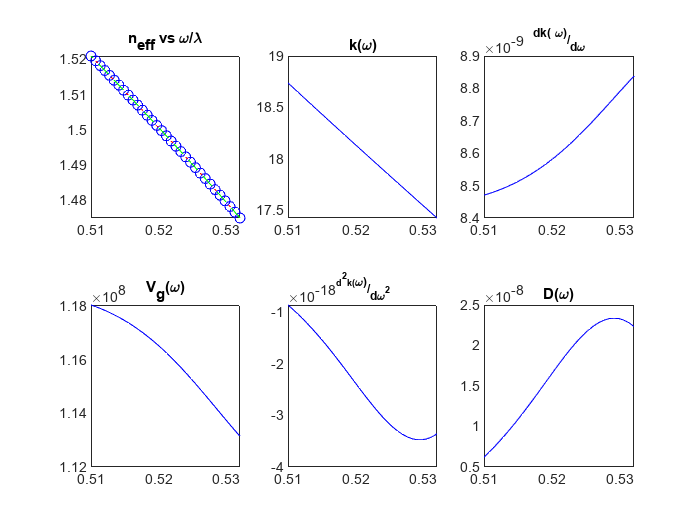

subplot(2,3,1);
plot(l,neff,'bo',l,wgSuperior.neffwFun(w),'r-.',l,wgSuperior.nefflFun(l),'g--');
title("n_{eff} vs \omega/\lambda");
subplot(2,3,2);
plot(l,wgSuperior.kwFun(w),'b');
title("k(\omega)");
subplot(2,3,3);
plot(l,wgSuperior.dkwdwFun(w),'b');
title("^{dk(\omega)}/_{d\omega}");
subplot(2,3,4);
plot(l,wgSuperior.vgwFun(w),'b');
title("V_g(\omega)");
subplot(2,3,5);
plot(l,wgSuperior.d2kwdw2Fun(w),'b');
title("^{d^2k(\omega)}/_{d\omega^2}");
subplot(2,3,6);
plot(l,wgSuperior.DwFun(w),'b');
title("D(\omega)");

##  Load Waveguide Simple:

 
file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
file = sprintf(Superior,sXs(sel),sYs(sel),mode);
load(SuperiorPath+file);
wgSuperior = waveguide(lambda,neff);

## K's comparing

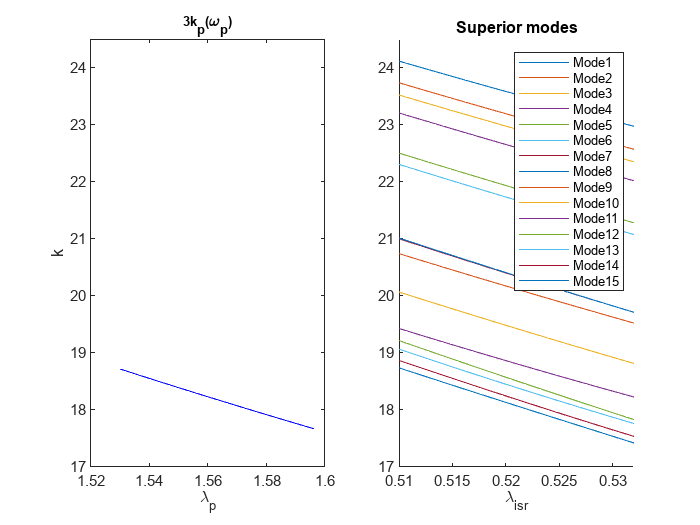

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
l = wgFundamental.lambdaData;
w = wgFundamental.omegaData;
neff = wgFundamental.neffData;
figure;
subplot(1,2,1)
plot(l,wgFundamental.kwFun(w).*3,'b');
leg = {};
title("3k_p(\omega_p)"); xlabel("\lambda_p"); ylabel("k");
ylim([17 24.5]);
subplot(1,2,2)
hold on
for i = 1:nmodes
    file = sprintf(Superior,sXs(sel),sYs(sel),i);
    load(SuperiorPath+file);
    wgSuperior = waveguide(lambda,neff);
    l = wgSuperior.lambdaData;
    w = wgSuperior.omegaData;
    plot(l,wgSuperior.kwFun(w));
    leg(end+1) = {"Mode"'+num2str(i)};
end
legend(leg);
ylim([17 24.5]);
title("Superior modes"); xlabel("\lambda_{isr}");
hold off

## Find degenerate photon that allow momentum and energy conservation

size=50;

lphLim = [min(wgFundamental.lambdaData) max(wgFundamental.lambdaData)];
lpLim = [min(wgSuperior.lambdaData) max(wgSuperior.lambdaData)];
lp = linspace(lpLim(1),lpLim(2),size);
wp = 2.*pi.*3.*10.^8./lp;
ws = wp./3;
leg = {};

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);

figure
hold on

dk0s = [];

for i = 1:nmodes
    file = sprintf(Superior,sXs(sel),sYs(sel),i);
    load(SuperiorPath+file);
    wgSuperior = waveguide(lambda,neff);
    %Nota w 10^8 es 10^14

    dk = wgSuperior.kwFun(wp)-(3*wgFundamental.kwFun(ws));

    if(min(dk)<=0 && max(dk)>=0)
        dk0s = [dk0s i];
    end

    plot(lp,dk);
    leg(end+1) = {"Mode"'+num2str(i)};
end

if ~isequal(dk0s,[])
    strDk0s = sprintf('Modo %i,',dk0s);
    strDk0s = "Modos con dK=0: "+strDk0s(1:end-1);
else
    strDk0s = "Ningun modo con dK=0";
end

disp(strDk0s)

Modos con dK=0: Modo 14,Modo 15


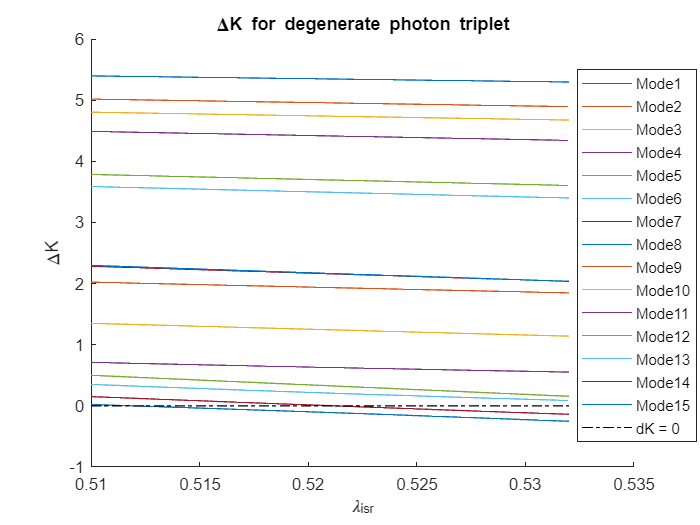


plot([lpLim(1),lpLim(2)],[0,0],'k-.')
leg(end+1) = {"dK = 0"};

legend(leg);
title("\DeltaK for degenerate photon triplet");
ylabel("\DeltaK"); xlabel("\lambda_{isr}");

legend("Position", [0.8256,0.15841,0.16964,0.70952])

## Phase Matching

switch nmodes
    case 15
        m = 5;n = 3;
    case 9
        m = 3;n = 3;
    case 19
        m = 5;n = 4;
    case 12
        m = 4;n = 3;
end

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);

lphLim = [min(wgFundamental.lambdaData) max(wgFundamental.lambdaData)];
lpLim = [min(wgSuperior.lambdaData) max(wgSuperior.lambdaData)];
li = 1.53;
size=50;

wp = linspace(2.*pi.*3.*10.^8./lpLim(1),2.*pi.*3.*10.^8./lpLim(2),size);
dw = linspace(1e8,-1e8,size);
[WP,DW] = meshgrid(wp,dw);
wi = (2.*pi.*3.*10.^8./li);
wr = DW+(WP-wi)/2;
ws = WP-wi-wr;

disp("Pump wavelength: "+num2str(lpLim(1))+"-"+num2str(lpLim(2)));

Pump wavelength: 0.51-0.532


disp("Photon wavelength: "+num2str(lphLim(1))+"-"+num2str(lphLim(2)));

Photon wavelength: 1.53-1.596


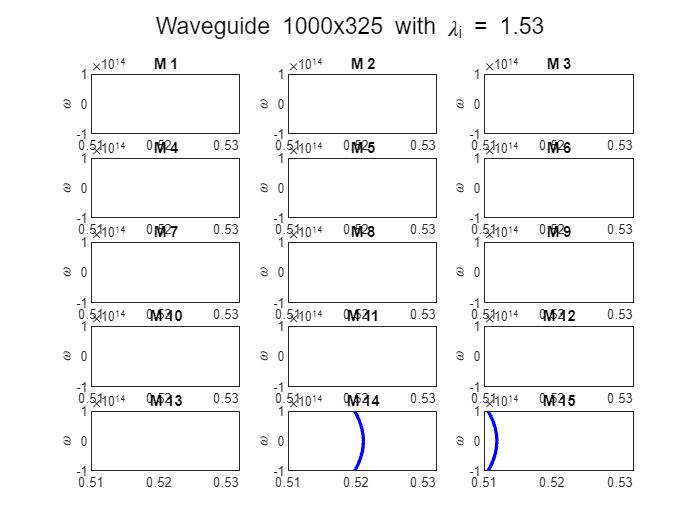

figure
for i = 1:nmodes
    file = sprintf(Superior,sXs(sel),sYs(sel),i);
    load(SuperiorPath+file);
    wgSuperior = waveguide(lambda,neff);
    %Nota w 10^8 es 10^14
    DK = wgSuperior.kwFun(WP)-(wgFundamental.kwFun(wi)+wgFundamental.kwFun(wr)+wgFundamental.kwFun(ws));
    subplot(m,n,i)
    contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'b','LineWidth',2);
    title("M "+num2str(i));
    ylabel("\omega");
end
sgtitle("Waveguide "+num2str(sXs(sel))+"x"+num2str(sYs(sel))+" with \lambda_i = "+num2str(li))